close all
clear all

% Función de transferencia de posición del motor
G = tf(273,[1  4.112 0]) % Planta del laboratorio pasado + integrador


G =
 
       273
  -------------
  s^2 + 4.112 s
 
Continuous-time transfer function.
Model Properties


%Parámetros de diseño
Tes = 4;
Mp = 0.2; % 20% < 40%
% Polos y ceros
sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -1.0000 + 1.9520i

s2 = -sigma-wd*1j

s2 = -1.0000 - 1.9520i


so = -2*sigma

so = -2

% Controlador
Td = -1/(2*so)

Td = 0.2500

Ti = 4*Td

Ti = 1

Gc_p = tf([Td*Ti Ti 1], [Ti 0])


Gc_p =
 
  0.25 s^2 + s + 1
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G


Gol =
 
  68.25 s^2 + 273 s + 273
  -----------------------
      s^3 + 4.112 s^2
 
Continuous-time transfer function.
Model Properties


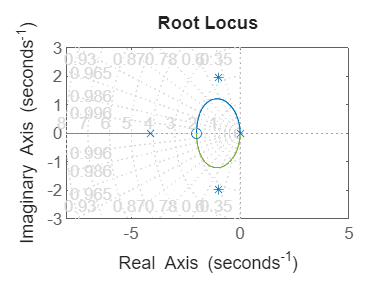

figure(1)
rlocus(Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
axis([-8 5 -3  3])
hold off

% K = 0.0669
Kp=0.0669;
%En lazo cerrado
Glc = feedback(Kp*Gol,1)


Glc =
 
     4.566 s^2 + 18.26 s + 18.26
  ---------------------------------
  s^3 + 8.678 s^2 + 18.26 s + 18.26
 
Continuous-time transfer function.
Model Properties


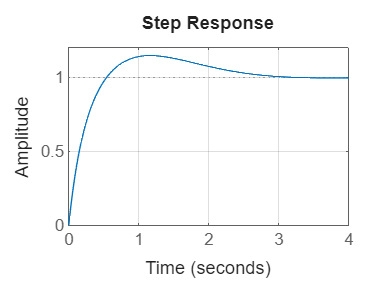


figure(2)
step(Glc);
grid on

% Tiempo de subida
Tr = 0.608 - 0.0268

Tr = 0.5812

T = 0.05

T = 0.0500

Datos_Xspace = [0.00  40.47  0.00  0.00
50.00  6.90  12.26  1.12
100.00  6.59  74.94  3.66
150.00  6.05  99.32  7.87
200.00  5.26  117.26  14.06
250.00  5.12  131.06  20.53
300.00  4.26  152.58  28.12
350.00  3.95  155.89  36.00
400.00  3.16  181.53  45.00
450.00  2.60  177.72  54.28
500.00  2.21  175.08  63.28
550.00  1.81  167.27  72.00
600.00  1.52  157.10  80.16
650.00  1.36  140.26  87.75
700.00  1.23  123.45  93.94
750.00  1.14  106.45  99.56
800.00  1.08  91.59  104.34
850.00  1.07  78.90  108.28
900.00  0.88  68.01  111.94
950.00  0.93  58.44  114.75
1000.00  0.80  49.16  117.28
1050.00  0.67  41.98  119.53
1100.00  0.68  33.84  121.22
1150.00  0.72  27.19  122.34
1200.00  0.56  22.58  123.47
1250.00  0.52  18.56  124.31
1300.00  0.38  15.29  125.16
1350.00  0.46  11.88  125.44
1400.00  0.47  11.05  125.44
1450.00  0.39  11.01  125.44
1500.00  0.30  11.00  125.44
1550.00  0.22  11.00  125.44
1600.00  0.13  11.00  125.44
1650.00  0.05  11.00  125.44
1700.00  -0.04  11.00  125.44
1750.00  -0.12  11.00  125.44
1800.00  -0.21  11.00  125.44
1850.00  -0.29  11.00  125.44
1900.00  -0.38  11.00  125.44
1950.00  -0.46  11.00  125.44
2000.00  -0.55  11.00  125.44
2050.00  -0.52  10.48  125.16
2100.00  -0.70  9.00  125.16
2150.00  -0.78  8.91  125.16
2200.00  -0.87  8.91  125.16
2250.00  -0.95  8.91  125.16
2300.00  -1.04  8.91  125.16
2350.00  -0.89  -0.16  124.59
2400.00  -0.71  -13.89  123.47
2450.00  -0.93  -16.97  122.91
2500.00  -0.74  -16.54  121.78
2550.00  -0.85  -17.30  120.94
2600.00  -0.86  -17.17  120.09
2650.00  -0.87  -17.82  119.25
2700.00  -0.76  -18.55  118.12
2750.00  -0.86  -19.18  117.28
2800.00  -0.86  -18.26  116.44
2850.00  -0.74  -18.60  115.31
2900.00  -0.82  -18.96  114.47
2950.00  -0.81  -17.50  113.62
3000.00  -0.80  -17.58  112.78
3050.00  -0.78  -18.15  111.94
3100.00  -0.65  -17.52  110.81
3150.00  -0.83  -17.27  110.25
3200.00  -0.71  -14.99  109.41
3250.00  -0.69  -15.23  108.56
3300.00  -0.77  -14.85  107.72
3350.00  -0.64  -13.98  107.16
3400.00  -0.72  -13.89  106.59
3450.00  -0.59  -12.94  105.75
3500.00  -0.66  -12.19  105.19
3550.00  -0.76  -11.37  104.91
3600.00  -0.64  -10.29  104.34
3650.00  -0.61  -11.42  103.78
3700.00  -0.59  -11.16  103.22
3750.00  -0.56  -9.55  102.66
3800.00  -0.64  -9.26  102.37
3850.00  -0.63  -8.29  102.09
3900.00  -0.50  -7.43  101.53
3950.00  -0.58  -7.56  101.25
4000.00  -0.57  -7.62  100.97
4050.00  -0.55  -6.39  100.69
4100.00  -0.53  -6.02  100.41
4150.00  -0.51  -5.31  100.12
4200.00  -0.50  -5.02  99.84
4250.00  -0.59  -4.83  99.84
4300.00  -0.59  -4.83  99.84
4350.00  -0.59  -4.83  99.84
4400.00  -0.59  -4.83  99.84
4450.00  -0.59  -4.83  99.84
4500.00  -0.59  -4.83  99.84
4550.00  -0.59  -4.83  99.84
4600.00  -0.59  -4.83  99.84
4650.00  -0.58  -4.83  99.84
4700.00  -0.58  -4.83  99.84
4750.00  -0.58  -4.83  99.84
4800.00  -0.58  -4.83  99.84
4850.00  -0.58  -4.83  99.84
4900.00  -0.58  -4.83  99.84
4950.00  -0.58  -4.83  99.84
5000.00  -0.58  -4.83  99.84
5050.00  -0.58  -4.83  99.84
5100.00  -0.58  -4.83  99.84
5150.00  -0.58  -4.83  99.84
5200.00  -0.58  -4.83  99.84
5250.00  -0.58  -4.83  99.84
5300.00  -0.58  -4.83  99.84
5350.00  -0.58  -4.83  99.84
5400.00  -0.58  -4.83  99.84
5450.00  -0.58  -4.83  99.84
5500.00  -0.58  -4.83  99.84
5550.00  -0.58  -4.83  99.84
5600.00  -0.57  -4.83  99.84
5650.00  -0.57  -4.83  99.84
5700.00  -0.57  -4.83  99.84
5750.00  -0.57  -4.83  99.84
5800.00  -0.57  -4.83  99.84
5850.00  -0.57  -4.83  99.84
5900.00  -0.57  -4.83  99.84
5950.00  -0.57  -4.83  99.84
6000.00  -0.57  -4.83  99.84
6050.00  -0.57  -4.83  99.84
];

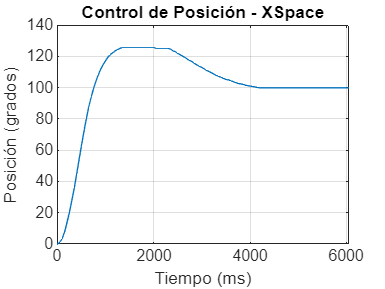

figure()
plot(Datos_Xspace(:,1), Datos_Xspace(:,4))
title('Control de Posición - XSpace')
ylabel('Posición (grados)')
xlabel('Tiempo (ms)')
grid on